# **Forward Kinematic exercise**

### **Grup 11- Estudiants:**

- **Pol Casacuberta Gil**

- **Marta Granero i Martí**

**Link: **[https://drive.matlab.com/sharing/b8a7f88a-dcb6-4c09-a328-ba6c7e737807](https://drive.matlab.com/sharing/b8a7f88a-dcb6-4c09-a328-ba6c7e737807)

Given the following 3R robot

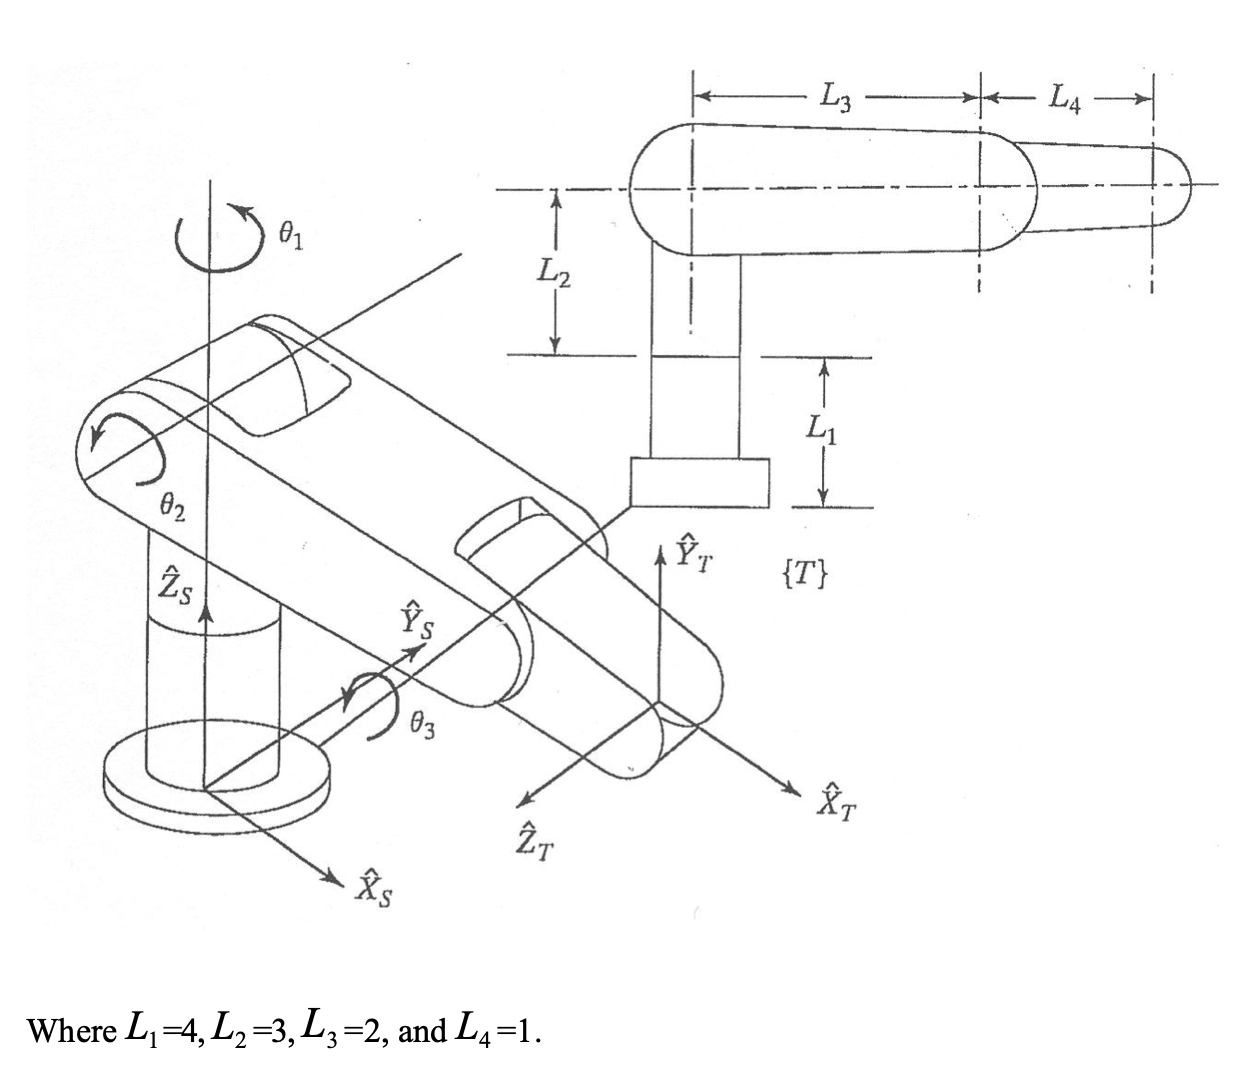

## Exercices

### 1) Draw on top of the figure the necessary frame

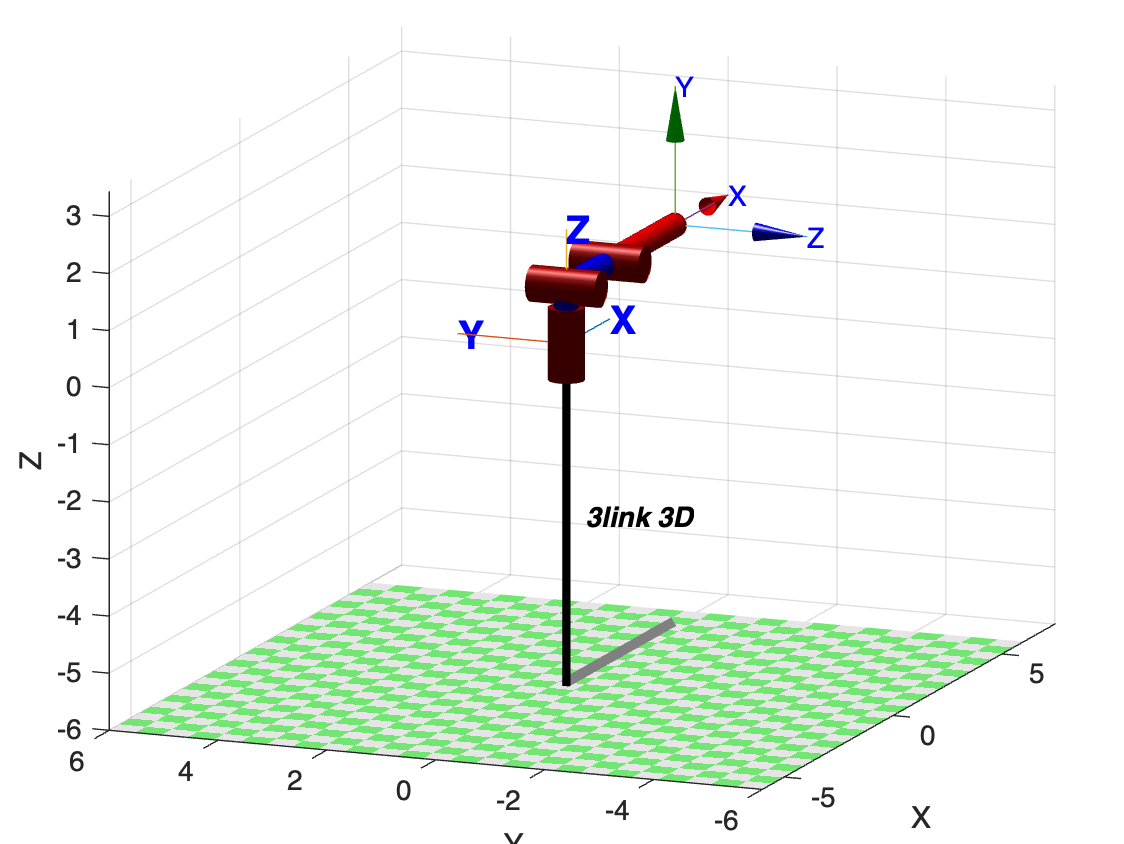

clear
clf
mdl_3link3d
hold on
trplot(eye(4), 'length', 2, 'arrow', 'width', 0.5, 'color','b', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
R3.plot([0 0 0])
v = [-20 -8 5];
[caz,cel] = view(v);
axis tight;

### 2) Derive the DH parameters table and the neighboring homogeneous transformation matrices ${}^{i-1}T_i$ for i=1,2,3, as functions of the joint angles

R3

 
R3 = 
 
3link 3D:: 3 axis, RRR, stdDH, slowRNE                           
 - Spong p106;                                                   
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          1|          0|     1.5708|          0|
|  2|         q2|          0|          2|          0|          0|
|  3|         q3|          0|          3|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 



T_1 = eye(4)* link_A_B_Std(R3.links(1).alpha, R3.links(1).a, R3.links(1).d, R3.links(1).theta)

T_1 =      1     0     0     0
     0     0    -1     0
     0     1     0     1
     0     0     0     1


T_2 = T_1 * link_A_B_Std(R3.links(2).alpha, R3.links(2).a, R3.links(2).d, R3.links(2).theta)

T_2 =      1     0     0     2
     0     0    -1     0
     0     1     0     1
     0     0     0     1


T_3 = T_2 * link_A_B_Std(R3.links(3).alpha, R3.links(3).a, R3.links(3).d, R3.links(3).theta)

T_3 =      1     0     0     5
     0     0    -1     0
     0     1     0     1
     0     0     0     1



%T_2_1 =  link_A_B_Std(R3.links(1).alpha, R3.links(1).a, R3.links(1).d, R3.links(1).theta)

T_2_1 =      1     0     0     0
     0     0    -1     0
     0     1     0     1
     0     0     0     1


%T_3_2 = link_A_B_Std(R3.links(2).alpha, R3.links(2).a, R3.links(2).d, R3.links(2).theta)

T_3_2 =      1     0     0     2
     0     1     0     0
     0     0     1     0
     0     0     0     1


%T_4_3 = link_A_B_Std(R3.links(3).alpha, R3.links(3).a, R3.links(3).d, R3.links(3).theta)

T_4_3 =      1     0     0     3
     0     1     0     0
     0     0     1     0
     0     0     0     1


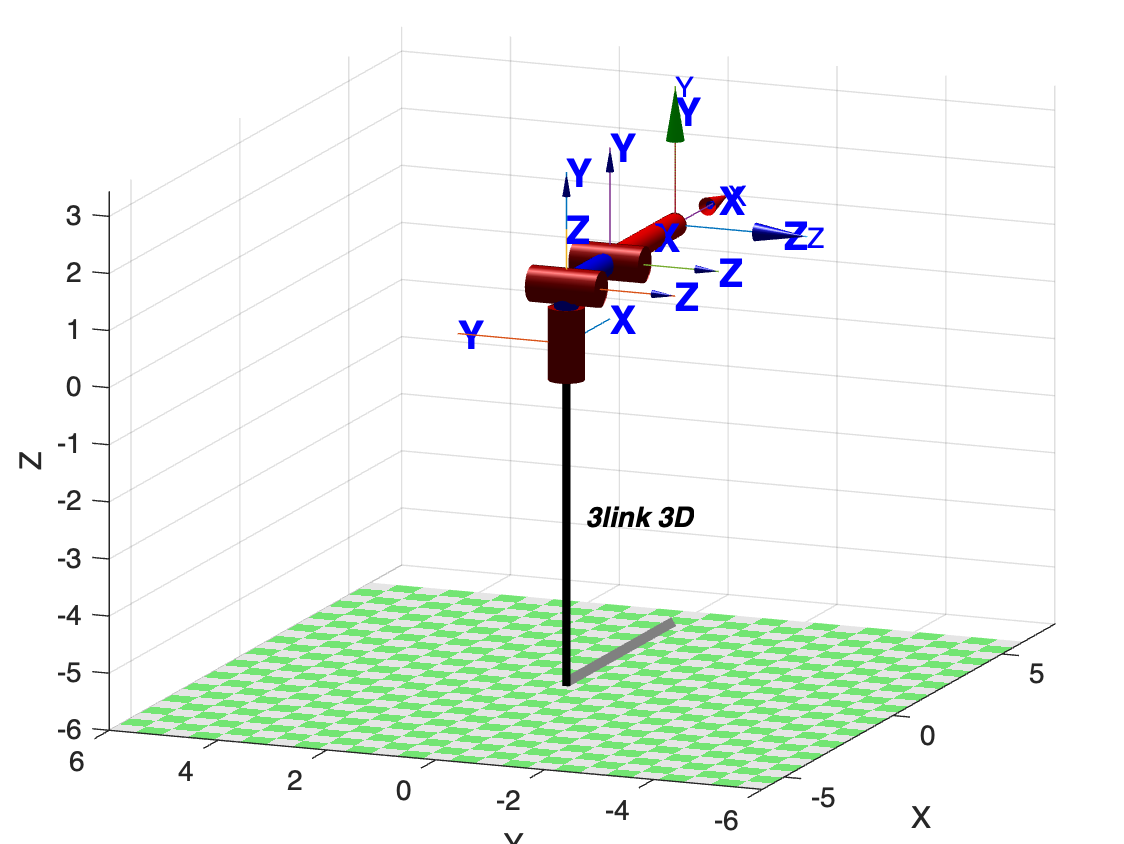


hold on


trplot(T_1, 'length', 2, 'arrow', 'width', 0.5, 'color','b', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T_2, 'length', 2, 'arrow', 'width', 0.5, 'color','b', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T_3, 'length', 2, 'arrow', 'width', 0.5, 'color','b', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
v = [-20 -8 5];
[caz,cel] = view(v);
axis tight;
hold off

### 3) Implement the forward kinematics, that is ${}^TT_S$

clf
mdl_3link3d

hold on
R3.plot([0 0 0])
v = [-20 -8 5];
[caz,cel] = view(v);
axis tight;

trplot(eye(4), 'length', 2, 'arrow', 'width', 0.5, 'color','b', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})

TT_s =T_2_1 * T_3_2 * T_4_3

TT_s =      1     0     0     5
     0     0    -1     0
     0     1     0     1
     0     0     0     1


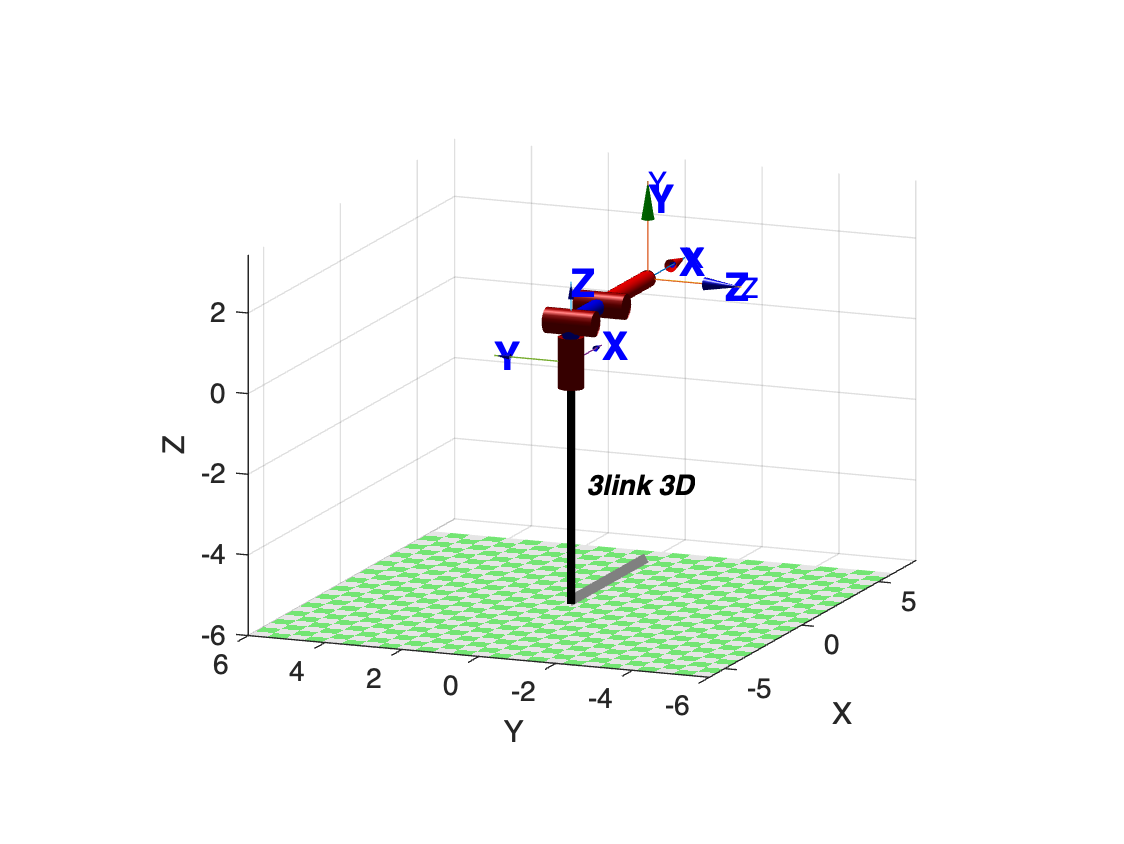

trplot(TT_s, 'length', 2, 'arrow', 'width', 0.5, 'color','b', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})

### 4) Calculate the result for the following joint angles: (0, 0, 0), (0, π/2, 0), and (0, π/2, π/6)

%(0,0,0)
clf
R3.plot([0 0 0])
hold on

T_3_4_1 = T_1 * trotz(0)

T_3_4_1 =      1     0     0     0
     0     0    -1     0
     0     1     0     1
     0     0     0     1


T_2_3_2 = T_2 * trotz(0)

T_2_3_2 =      1     0     0     2
     0     0    -1     0
     0     1     0     1
     0     0     0     1


T_1_2_3 = T_3 * trotz(0)

T_1_2_3 =      1     0     0     5
     0     0    -1     0
     0     1     0     1
     0     0     0     1


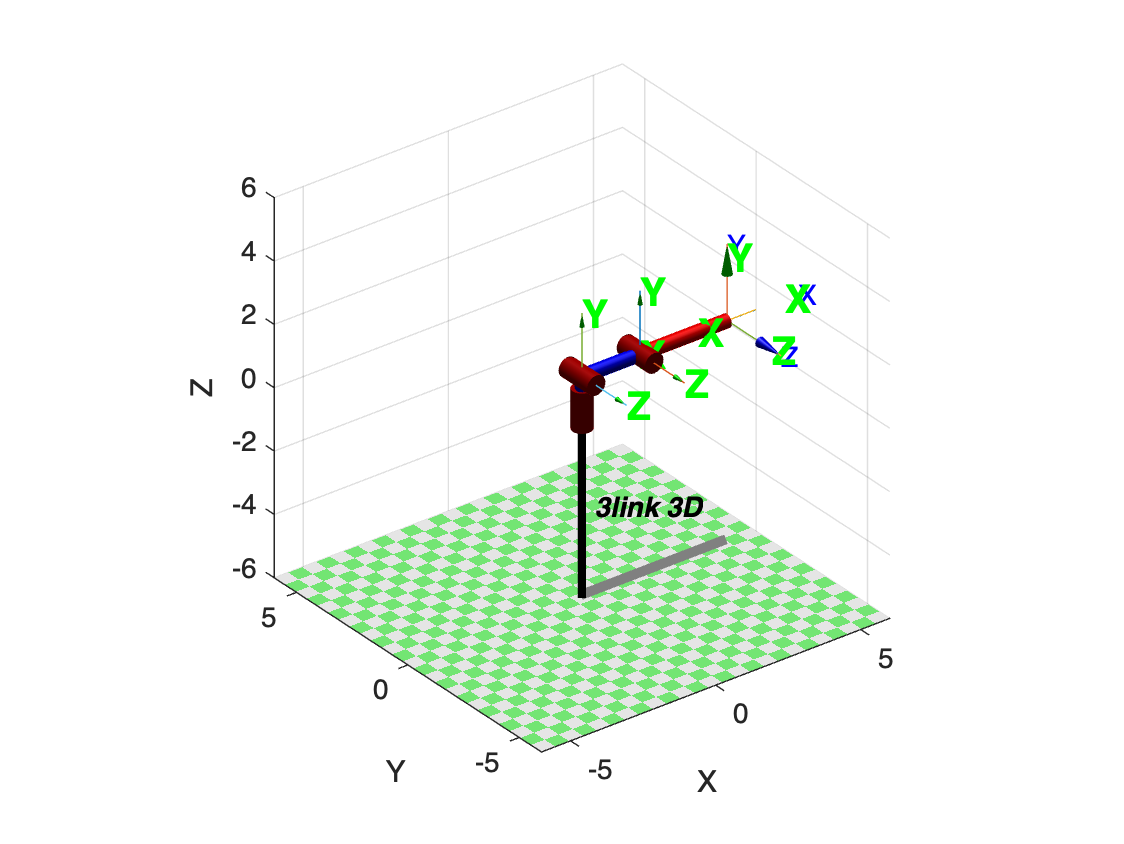


trplot(T_3_4_1, 'length', 2, 'arrow', 'width', 0.5, 'color','g', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T_2_3_2, 'length', 2, 'arrow', 'width', 0.5, 'color','g', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T_1_2_3, 'length', 2, 'arrow', 'width', 0.5, 'color','g', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
hold off

%(0,pi/2,0)
clf
R3.plot([0 0 0])
hold on
T_3_4_1 = T_1 * trotz(0)

T_3_4_1 =      1     0     0     0
     0     0    -1     0
     0     1     0     1
     0     0     0     1


T_2_3_2 = T_2 * trotz(pi/2)

T_2_3_2 =      0    -1     0     2
     0     0    -1     0
     1     0     0     1
     0     0     0     1


T_1_2_3 = T_3 * trotz(0)

T_1_2_3 =      1     0     0     5
     0     0    -1     0
     0     1     0     1
     0     0     0     1


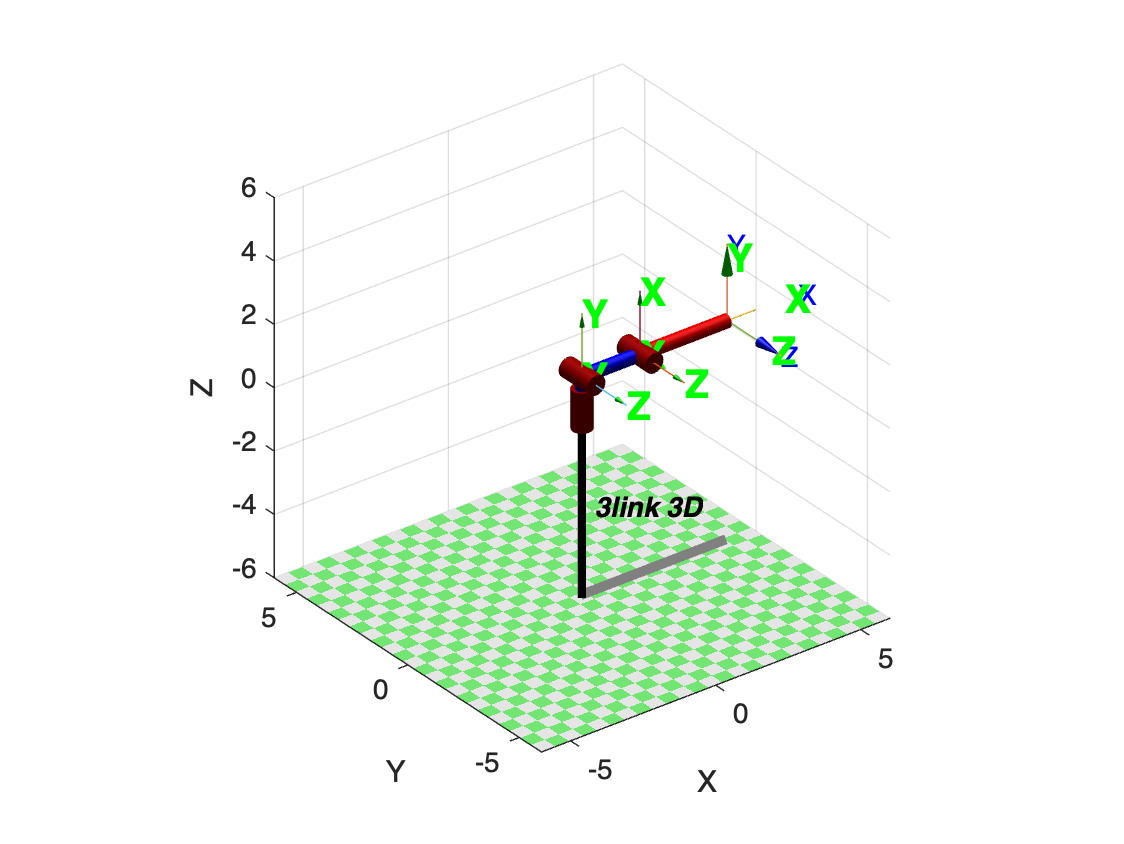


trplot(T_3_4_1, 'length', 2, 'arrow', 'width', 0.5, 'color','g', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T_2_3_2, 'length', 2, 'arrow', 'width', 0.5, 'color','g', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T_1_2_3, 'length', 2, 'arrow', 'width', 0.5, 'color','g', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
hold off

%(0,pi/2,pi/6)
clf
R3.plot([0 0 0])
hold on
T_3_4_1 = T_1 * trotz(0)

T_3_4_1 =      1     0     0     0
     0     0    -1     0
     0     1     0     1
     0     0     0     1


T_2_3_2 = T_2 * trotz(pi/2)

T_2_3_2 =      0    -1     0     2
     0     0    -1     0
     1     0     0     1
     0     0     0     1


T_1_2_3 = T_3 * trotz(pi/6)

T_1_2_3 =     0.8660   -0.5000         0    5.0000
         0         0   -1.0000         0
    0.5000    0.8660         0    1.0000
         0         0         0    1.0000


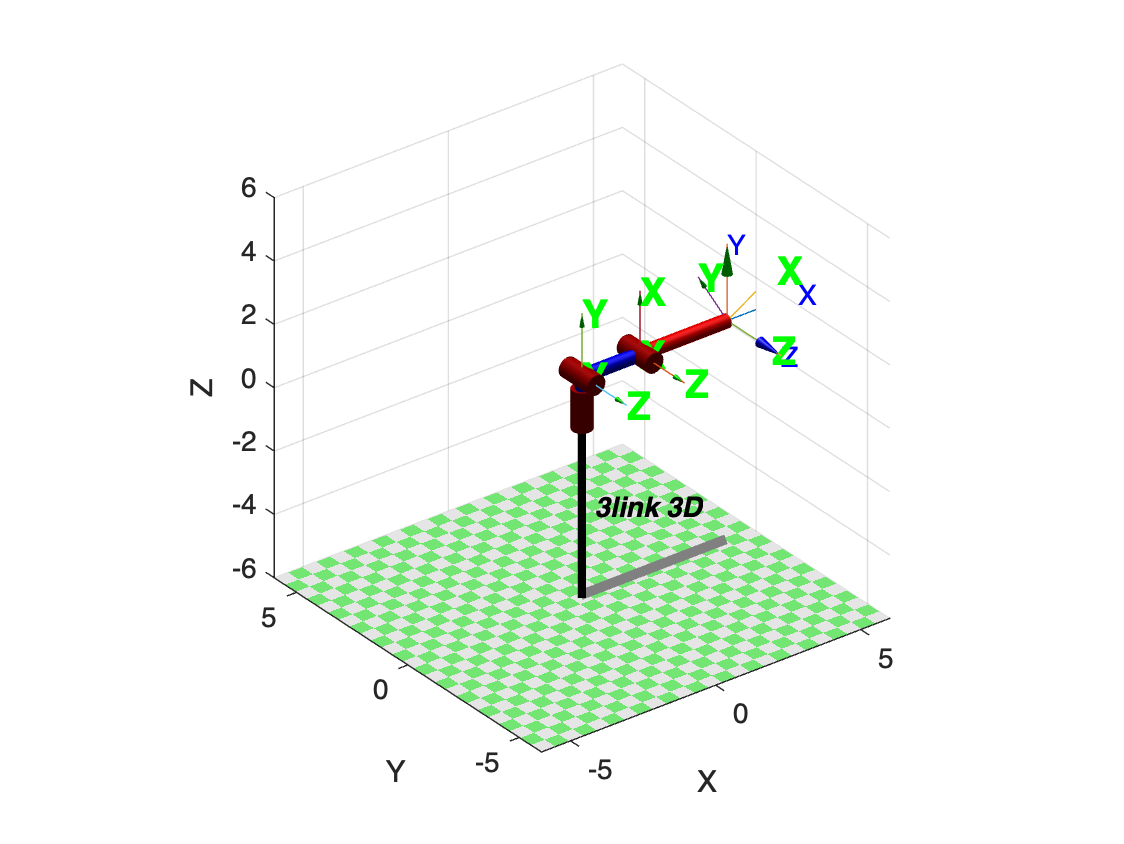


trplot(T_3_4_1, 'length', 2, 'arrow', 'width', 0.5, 'color','g', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T_2_3_2, 'length', 2, 'arrow', 'width', 0.5, 'color','g', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T_1_2_3, 'length', 2, 'arrow', 'width', 0.5, 'color','g', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
hold off

function T = Std_link_A_B(alpha, a, d, theta)
% Computes the homogeneous transformation matrix from frame A to frame B
% using the standard Denavit-Hartenberg parameters alpha, a, d, and theta.

T = [cos(theta)              -sin(theta)             0              a;
     sin(theta)*cos(alpha)  cos(theta)*cos(alpha)  -sin(alpha)   -d*sin(alpha);
     sin(theta)*sin(alpha)  cos(theta)*sin(alpha)   cos(alpha)    d*cos(alpha);
     0                      0                       0             1];
end

function T_b_a=link_A_B_Md(alpha,a,d,theta)
T_b_a=trotx(alpha)*transl(a,0,0)*trotz(theta)*transl(0,0,d);
end

function T_b_a=link_A_B_Std(alpha,a,d,theta)
T_b_a=trotz(theta)*transl(0,0,d)*transl(a,0,0)*trotx(alpha);
end

function plotCoordFrame(T, L)
    % Extract the translation and rotation from the transformation matrix
    R = T(1:3,1:3);
    p = T(1:3,4);
    
    % Define the endpoints for the coordinate frame axes
    x_end = p + L*R(:,1);
    y_end = p + L*R(:,2);
    z_end = p + L*R(:,3);
    
    % Plot the coordinate frame axes
    line([p(1) x_end(1)], [p(2) x_end(2)], [p(3) x_end(3)], 'Color', 'r', 'LineWidth', 2);
    line([p(1) y_end(1)], [p(2) y_end(2)], [p(3) y_end(3)], 'Color', 'g', 'LineWidth', 2);
    line([p(1) z_end(1)], [p(2) z_end(2)], [p(3) z_end(3)], 'Color', 'b', 'LineWidth', 2);
end